# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter

global D h k;
down_sample_amount = 5;

% Circle
D = .8; k = 20; h = 0.02;
position = importdata("position_Array.mat");


l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
      
state(:,1) =[position(1,1); position(2,1); 0];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;

for t =1 : T
%     n1 = randn(1);
%     n2 = randn(1);
    n1 = 0;
    n2 = 0;
    % x= current state
    
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w,n1,n2);

     linear_vel(t) = v+n1;
     angular_vel(t) = w+n2;
     
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [(v+n1)*cos(state(3,t)); (v+n1)*sin(state(3,t)); w+n2];     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = atan2((state(2,t+1)-state(2,t))/(v+n1),(state(1,t+1)-state(1,t))/(v+n1)) + dot_x(3)*h;
%     theta(t+1) = theta(t) + dot_x(3)*h;

end

ans = 6.2425

ans = 7.7411

ans = 8.2301

ans = 8.0703

ans = 7.6376

ans = 7.1687

ans = 6.7666

ans = 6.4557

ans = 6.2268

ans = 6.0607

ans = 5.9396

ans = 5.8490

ans = 5.7786

ans = 5.7216

ans = 5.6733

ans = 5.6307

ans = 5.5922

ans = 5.5566

ans = 5.5231

ans = 5.4916

ans = 5.4616

ans = 5.4332

ans = 5.4061

ans = 5.3805

ans = 5.3561

ans = 5.3331

ans = 5.3113

ans = 5.2907

ans = 5.2713

ans = 5.2530

ans = 5.2358

ans = 5.2197

ans = 5.2046

ans = 5.1904

ans = 5.1771

ans = 5.1647

ans = 5.1531

ans = 5.1422

ans = 5.1321

ans = 5.1227

ans = 5.1139

ans = 5.1057

ans = 5.0981

ans = 5.0910

ans = 5.0844

ans = 5.0783

ans = 5.0726

ans = 5.0673

ans = 5.0623

ans = 5.0578

ans = 5.0535

ans = 5.0496

ans = 5.0459

ans = 5.0426

ans = 5.0394

ans = 5.0365

ans = 5.0338

ans = 5.0313

ans = 5.0290

ans = 5.0268

ans = 5.0248

ans = 5.0230

ans = 5.0213

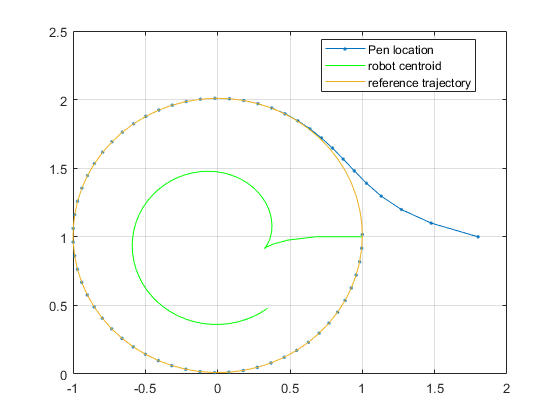


% save("noise_centroid.mat","state")

figure
plot(xb, yb, '.-')
hold on;
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:));
grid on;
legend('Pen location', 'robot centroid', 'reference trajectory', "location", 'best')
hold off

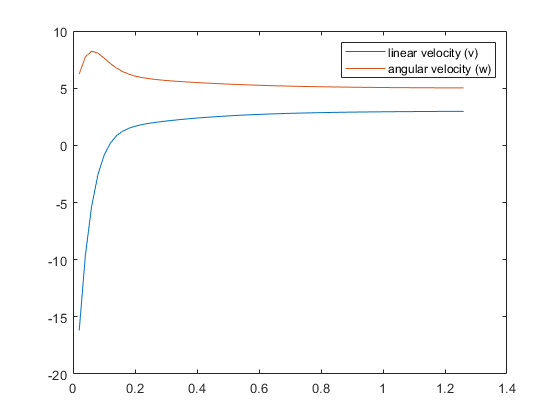


figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('linear velocity (v)', 'angular velocity (w)')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end